clear;
close all;
% 1
image = imread('img/bob.JPG');
maskedRGBImage = load('maskedRGBImage.mat').maskedRGBImage;
imshow(image);

imwrite(image, '1_output.png');

% 2.a
r = image(:, :, 1);
g = image(:, :, 2);
b = image(:, :, 3);
figure;
subplot(3, 1, 1);
imshow(r);
subplot(3, 1, 2);
imshow(g);
subplot(3, 1, 3);
imshow(b);

% 2.b
figure;
image_grayscaled = rgb2gray(image);
imshow(image_grayscaled)

% 3.a,b
threshold = 100;
imageBlackWhite = image_grayscaled > threshold;

figure;
imshow(imageBlackWhite);
title('Black&White')

% 3.c
% Extract the HSV components
hsvImg = rgb2hsv(image);
hue = hsvImg(:, :, 1);
saturation = hsvImg(:, :, 2);
value = hsvImg(:, :, 1);
% Define the mask for the green hue range
mask = (hue >= 0.20) & (hue <= 0.45);
% Apply the mask to the image
filteredImage = image;
filteredImage(:, :, 1) = filteredImage(:, :, 1) .* uint8(mask);
filteredImage(:, :, 2) = filteredImage(:, :, 2) .* uint8(mask);
filteredImage(:, :, 3) = filteredImage(:, :, 3) .* uint8(mask);

%r_removed = r < 0;
%b_removed = b < 0;
%imageRemoved = image;
%imageRemoved(:, :, 1) = r_removed;
%imageRemoved(:, :, 3) = b_removed;
% Plot the mask and filtered image
figure;
subplot(1, 3, 1);
imshow(image);
title('Original image');
subplot(1, 3, 2);
imshow(mask);
title('Mask');
subplot(1, 3, 3);
imshow(filteredImage);
title('Filtered image');

% 3.d
figure;
greenMask = rgb2gray(maskedRGBImage);
imshow(greenMask)
imageChange = image;
for i = 1:1920
    for j = 1:2560
        if greenMask(i, j, 1) > 0
            imageChange(i, j, 3) = greenMask(i, j, 1);
            imageChange(i, j, 2) = 0.6 * greenMask(i, j, 1);
            imageChange(i, j, 1) = 0;
        else
        end
    end
end
imshow(imageChange);

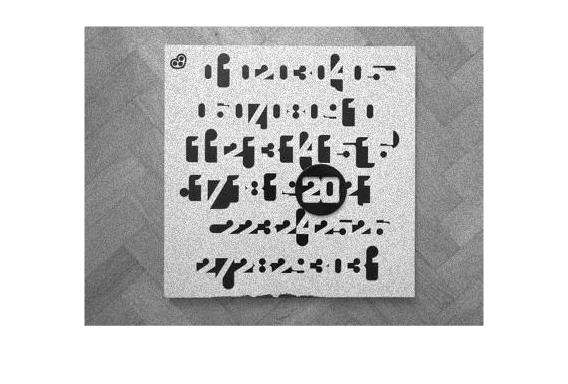

% 4.a,b
calendar = im2double(imread('img/calendar_speckle10.jpg'));

% Soble filter
sobel = fspecial('sobel');
edge = conv2(calendar, sobel, 'same');

% Gaussian smoothing
calendarSmoothed = imgaussfilt(calendar, 2);
imshow(calendar);

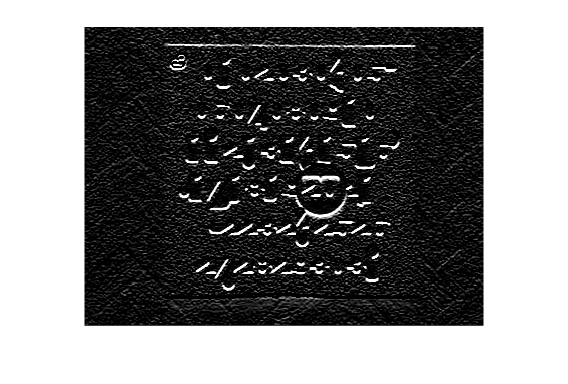

imshow(edge);

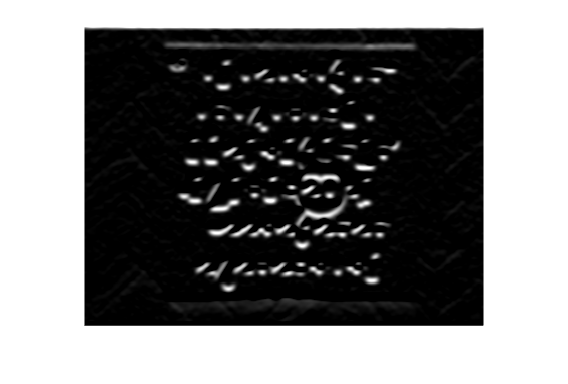

% 4.c
edgeBlured = imgaussfilt(edge, 2);
imshow(edgeBlured);


% 4.d
sobelHorizontal = fspecial('sobel');
sobelVertical = sobelHorizontal';

tic
for i = 1:1000
    A = conv2(conv2(calendarSmoothed, sobelHorizontal, 'same'), sobelVertical, 'same');
end
timeA = toc;

tic
for i = 1:1000
    B = conv2(conv2(calendarSmoothed, sobelVertical, 'same'), sobelHorizontal, 'same');
end
timeB = toc;

disp('A')

A


disp(timeA);

    0.4082




disp('B');

B


disp(timeB);

    0.4460



% 5
load("calibrationSession.mat");

figure;
imshow(pen1); % 242 pixels image 1
% (475, 831) pixles center (5cm + 7.5cm -> to pixels)
cameraParams = calibrationSession.CameraParameters;
%p = cameraParams.PatternExtrinsics.transformPointsInverse([475; 831; 1])
imshow(pen2); % 224 pixels image 2
Xc = 140;
measured_length_pen1 = 540;
measured_length_pen2 = 486;

disp(cameraParams.FocalLength);

depth_pen1 = (cameraParams.FocalLength(1) * Xc) / measured_length_pen1;
disp(['depth_pen1:', num2str(depth_pen1),'mm']);

depth_pen2 = (cameraParams.FocalLength(2) * Xc) / measured_length_pen2;
disp(['depth_pen2:', num2str(depth_pen2),'mm']);

% c
pen1_undistorted = undistortImage(pen1, cameraParams, 'OutputView', 'full');
pen2_undistorted = undistortImage(pen2, cameraParams, 'OutputView', 'full');
imshow(pen1_undistorted);
imshow(pen2_undistorted);
measured_length_pen1_undistorted = 537;
measured_length_pen2_undistorted = 546;

depth_pen1_undistorted = (cameraParams.FocalLength(1) * Xc) / measured_length_pen1_undistorted;
disp(['depth_pen1_undistored:', num2str(depth_pen1_undistorted),'mm']);

depth_pen2_undistorted = (cameraParams.FocalLength(2) * Xc) / measured_length_pen2_undistorted;
disp(['depth_pen2_undistorted:', num2str(depth_pen2_undistorted),'mm']);

% Bonus
hsv = rgb2hsv(pen2);
range = 0.9;
pen1_size = size(hsv);
targetLow = (hsv(1) - range + 1) - floor(hsv(1) - range + 1);
targetHigh = (hsv(1) + range) - floor(hsv(1) + range);

min = 5/360;
max = 320/360;
hsv(:, :, 3) = hsv(:, :, 1) < min;
%hsv(:, :, 3) = hsv(:, :, 1) > max;

%pen_1_red = pen_1_red > 100;
rgb = hsv2rgb(hsv);
imshow(rgb);
props = regionprops(rgb, 'Area', 'BoundingBox');